% Kym Derriman (Partner: Evan Howell)
% Lab 6: Damped Harmonic Motion
% 10/17/2024

% --------------------------------------------
% Spring Force vs Displacement Analysis (500g)
% --------------------------------------------

% ----------------------------------------------
% Import and Prepare Measured Data weight = 500g
% ----------------------------------------------

% Data from oscillating spring with 500g weight attached.

tbl = readtable("L6_500g_Oscillation.txt");
times = tbl.Time;
positions = tbl.Position;
velocities = tbl.Velocity;
accelerations = tbl.Acceleration;

% Prepare data to plot oscillation about zero.

% Calculate the means 
position_means = mean(positions);
%vel_means = mean(velocities);
%accel_means = mean(accelerations);

% Shift plots down by subtracting means from measured values.
shifted_positions = positions - position_means;
%shifted_velocities = velocities - vel_means;
%shifted_accelerations = accelerations - accel_means;

% Convert position data to displacement data and shift all to oscillate
% about zero
x0 = shifted_positions(1);
%v0 = shifted_velocities(1);
%a0 = shifted_accelerations(1);

displ_invert = x0 - shifted_positions;
%veloc_invert = v0 - shifted_velocities;
%accel_invert = a0 - shifted_accelerations;

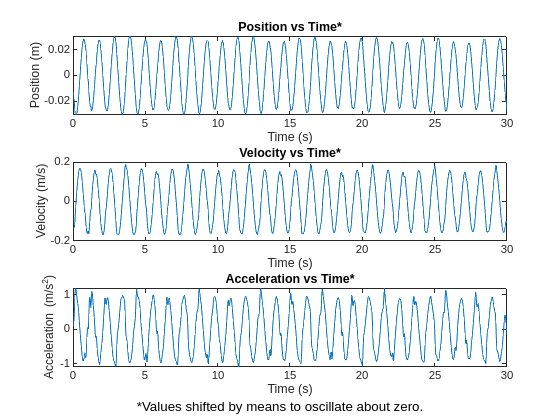

% --------------------------------------------------
% Plot Displacement, Velocity, Acceleration Data
% --------------------------------------------------

% Plot non-shifted, non-inverted data
figure;

% Subplot 1: Position
subplot(3, 1, 1); plot(times, shifted_positions);
title('Position vs Time*'); xlabel('Time (s)'); ylabel('Position (m)');

% Subplot 2: Velocity
subplot(3, 1, 2); plot(times, velocities);
title('Velocity vs Time*'); xlabel('Time (s)'); ylabel('Velocity (m/s)');

% Subplot 3: Acceleration
subplot(3, 1, 3); plot(times, accelerations);
title('Acceleration vs Time*'); xlabel('Time (s)'); ylabel('Acceleration (m/s^2)');

% Add annotation to indicate the asterisk explanation
annotation('textbox', [0.1, 0.01, 0.8, 0.05], 'String', ...
    '*Values shifted by means to oscillate about zero.','EdgeColor', 'none', ...
    'HorizontalAlignment', 'center', 'FontSize', 10);